## Establishing connection to hardware. This process can take several seconds.


ans = logical
   1


## Establishing connection to hardware. This process can take several seconds.


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


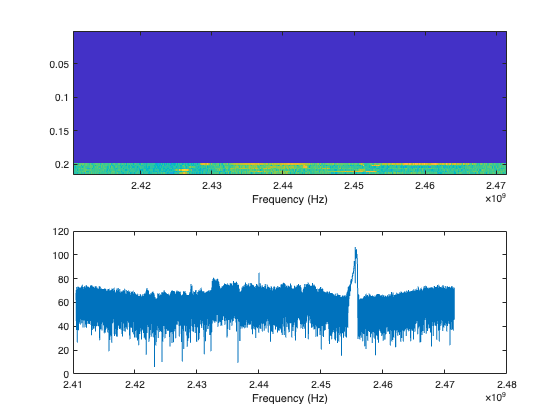

ans = logical
   1


% Create PlutoSDR object
clear

pluto1_ID = 'usb:0';
pluto2_ID = 'usb:1';

pluto0Receive = sdrrx('Pluto','RadioID','usb:0');
pluto0Transmit = sdrtx('Pluto','RadioID','usb:0');

pluto1Receive = sdrrx('Pluto','RadioID','usb:1');
pluto1Transmit = sdrtx('Pluto','RadioID','usb:1');

% plutoradio = sdrdev('Pluto');
% plutoradio.RadioID = 'ip:192.168.2.1';


fc = 2441e6; % bluetooth
% fs = 6.144e+07;

fs = 61e6; % <= 6.144e+07

% fc = 98e6; % FM radio (requires small firmware adjustment)
% fs = 20e6; % .4 MHz per channel

% DTV: 6MHz per channel
% Channels 14-36 (470-608 MHz)
% less commonly:
% Low VHF: Channels 2-6 (54-88 MHz)
% High VHF: Channels 7-13 (174-216 MHz)

pluto0Receive.CenterFrequency = fc;
pluto0Receive.BasebandSampleRate = fs;
pluto0Receive.GainSource = 'Manual';
pluto0Receive.Gain = 40;


pluto0Transmit.CenterFrequency = fc; % needs to be the same
pluto0Transmit.BasebandSampleRate = fs; % needs to be the same


% Setup spectrogram parameters
fftSize = 2^17;
window = blackman(fftSize);
numRows = 100;
specData = zeros(numRows, fftSize);

% Setup frequency axis
freq = (-fftSize/2:fftSize/2-1)*(fs/fftSize) + fc;

% Setup plot
figure(1)
% colorbar;
% ylabel('Time');
% title('WiFi Spectrum');
% clim([-120 0]);
% grid on;
time = (1:numRows)*fftSize/fs;

% Capture and display data continuously
tic
for i = 1:numRows
    % transmit
    f = 0.1;
    wf = exp(2i*pi*f*(1:fftSize)).';
    pluto0Transmit(wf)


    % recieve
    dataInt = pluto0Receive.capture(fftSize);


    % Compute FFT
    data = single(dataInt);
    spectrum = fftshift(fft(data .* window));
    powerDb = 10*log10(abs(spectrum).^2);

    specData = [specData(2:end,:);powerDb'];

    subplot(2,1,1)
    imagesc(freq,time,specData)
    xlabel('Frequency (Hz)');

    subplot(2,1,2)
    plot(freq,powerDb)
    xlabel('Frequency (Hz)');

    % pause(.001)
    drawnow

end

toc % keeping time helps you to l

% Clean up
release(pluto0Receive)
release(pluto0Transmit)